# Train DDPG Agent for Balancing a Ball on a Beam

In this live script, the reinforcement learning environment, deep deterministic policy gradient (DDPG) agent, and training routine are setup and training can be executed.

## Model

Open the model.

mdl = 'BaB_RL_V8';
open_system(mdl)

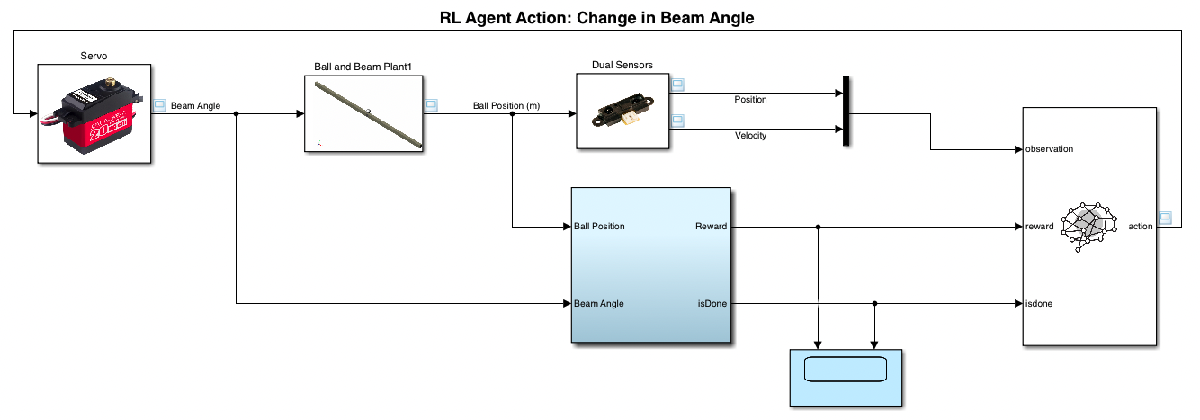

For this model:

- The ball at the center of the beam is 0 meters, the ball at the left of the beam is -0.28 meters, and the ball at the right of the beam is 0.28 meters

- The servo-input action signal from the agent to the environment is from -14 degrees to 14 degrees (may be adjusted based on 'cs.MaxInput')

- The observations from the environment are the ball position and velocity, with no sensor noise.

- The reward $r_t$, provided at every time step, is


$$r_t =\exp \left(-0\ldotp 01*{\left(100*x_t \right)}^2 \right)-0\ldotp 05{\left(\frac{\delta u}{\delta t}\right)}^2$$


Here:

- $x_t$ is the ball position at that time step

- $\frac{\delta u}{\delta t}$ is the instantaneous change in servo input

#### Model Settings

Specify the max input angle in the servo compatible 0.01 to 1.00 scale.

cs.MaxInput = 0.05; % Unit~7.2 degrees

Load the sensor noise mat file which has already been integrated to the Simulink model.

load('SensorNoise.mat')
sensor.pos_all = pos_all; clear pos_all
sensor.pos_all_cm = sensor.pos_all/100; % convert to meters
sensor.var_pos_all_cm = var(sensor.pos_all_cm)*2; 
sensor.SampleTime = 0.03;
% sensor.NoisePower = sensor.var_pos_all_cm*sensor.SampleTime;
sensor.NoisePower = 0; % No noise in first training session!

Define the lowpass filter parameters on the sensors:

sensor.R = 100000; % Ohms
sensor.C = 1*10^-6; % Farads

Load the servo response mat file which was derived using the System Identification toolbox and which has already been integrated to the Simulink model.

% load('tf4_75v.mat')
s = tf('s');
servo_tf = 200/(s^2+20*s+200);

Define the sample time `Ts` and simulation duration `Tf` in seconds. 

*For Reference: The PID controlled system reaches steady-state in approximately 3 seconds*

Ts = 0.03;
Tf = 10;

Define the mathematical description of system.

theory.m = 2.7/1000; % kg
theory.R = 0.02; % meters
theory.g = -9.8; % m/s^2
theory.J = (2/3)*theory.m*theory.R^2; % kg m^2

% Plant Numerator
theory.H = -theory.m*theory.g/(theory.J/(theory.R^2)+theory.m); % m/s^2

Define starting location (to be randomized).

IC = 0.2; % meters

## Create Environment Interface

Create a reinforcement learning environment interface for the model.

Create the observation specification.

observationInfo = rlNumericSpec([2 1],...
    'LowerLimit',[-0.281 -30]',...
    'UpperLimit',[0.281  30]');
observationInfo.Name = 'observations';
observationInfo.Description = 'position and velocity';
obsInfo = observationInfo;

Create the action specification.

actionInfo = rlNumericSpec([1 1]);
actionInfo.Name = 'servoInput';
actionInfo.UpperLimit = cs.MaxInput; % 0-1 input scale, instantaneous input change request
actionInfo.LowerLimit = -cs.MaxInput; % 0-1 input scale, instantaneous input change request
actInfo = actionInfo;

Create the environment interface.

env = rlSimulinkEnv(mdl,[mdl '/RL Agent'],observationInfo,actionInfo);

Randomize the inital starting location of the ball at the start of each episode.

% env.ResetFcn = @(in)localResetFcn(in);
env.ResetFcn = @(in) setVariable(in, 'IC', datasample([-1,1],1)*(0.24-0.08*rand), 'Workspace', mdl);

## Create DDPG Agent

A DDPG agent approximates the long-term reward, given observations and actions, using a critic value function representation. To create the critic, first create a deep neural network with two inputs (the state and action) and one output. For more information on creating a neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

numObservations = 2;
nodes = 4;
statePath = imageInputLayer([numObservations 1 1],'Normalization','none','Name','observation');
actionPath = imageInputLayer([1 1 1],'Normalization','none','Name','action');
commonPath = [concatenationLayer(1,2,'Name','Concatenation')
%              tanhLayer('Name','tanh1Layer')
             fullyConnectedLayer(nodes,'Name','Critic Fully Connected Layer 1')
             tanhLayer('Name','Hyperbolic Tangent Layer 1')
             fullyConnectedLayer(2,'Name','Critic Fully Connected Layer 2')
             tanhLayer('Name','Hyperbolic Tangent Layer 2')
             fullyConnectedLayer(1,'Name','State Value','BiasLearnRateFactor',0,'Bias',0)];

criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);

criticNetwork = connectLayers(criticNetwork,'observation','Concatenation/in1');
criticNetwork = connectLayers(criticNetwork,'action','Concatenation/in2');

% try to use a fully connected layer for the action with the same # of
% nodes as for the critic

% then we can combine both outputs with a fully connected network with a
% variable # of nodes (< 10)

% then a sigmoidal layer up to 10 nodes

% then a fully connected network with just 1 node

% Don't go too far away from the example that uses the second-order integrator ---

View the critic network configuration.

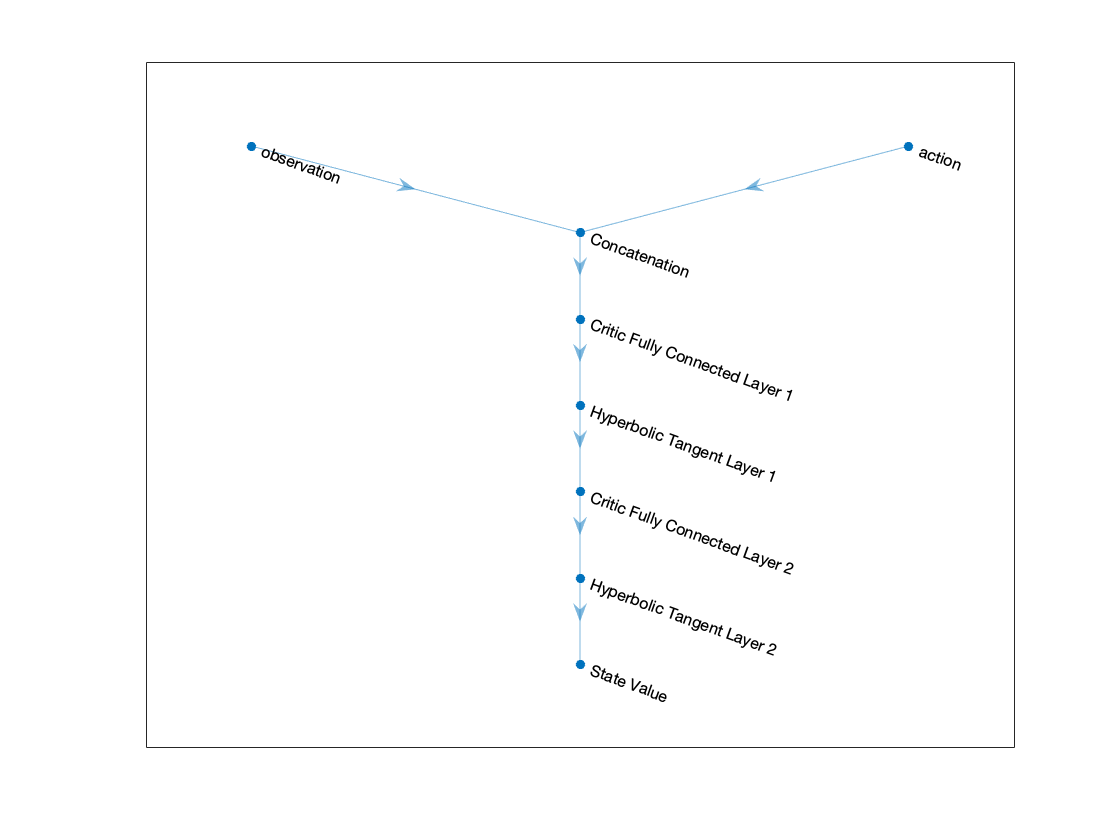

figure
plot(criticNetwork)

Specify options for the critic representation using [`rlRepresentationOptions`](docid:rl_ref#mw_45ccf57d-64f0-4822-8000-3f0f44f2572e).

criticOptions = rlRepresentationOptions('LearnRate',1e-3,'GradientThreshold', 1);

Create the critic representation using the specified deep neural network and options. You must also specify the action and observation information for the critic, which you already obtained from the environment interface. For more information, see [`rlQValueRepresentation`](docid:rl_ref#mw_6e9cf856-c679-4834-97e1-1349c4a21e43).

critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,...
    'Observation',{'observation'},'Action',{'action'},criticOptions);

A DDPG agent decides which action to take, given observations, using an actor representation. To create the actor, first create a deep neural network with one input (the observation) and one output (the action).

Construct the actor in a similar manner to the critic. For more information, see [`rlDeterministicActorRepresentation`](docid:rl_ref#mw_425a8728-2966-45c4-9d2a-488aa4a506bf).

% actorNetwork = [
%     featureInputLayer(numObservations,'Normalization','none','Name','observation')
%     fullyConnectedLayer(12,'Name','ActorFC1')
%     sigmoidLayer('Name','ActorSigmoid1', ) % make sure I am starting with a sigmoidal function that outputs both positive and negative! Also, try to start with a low inclination - will look like a linear function
%     fullyConnectedLayer(12,'Name','ActorFC2')
%     sigmoidLayer('Name','ActorSigmoid2')
%     fullyConnectedLayer(1,'Name','ActorFC3')
%     sigmoidLayer('Name','ActorSigmoid3')
%     scalingLayer('Name','ActorScaling','Scale',max(actInfo.UpperLimit))];

% actorNetwork = [
%     featureInputLayer(numObservations,'Normalization','none','Name','observation')
%     fullyConnectedLayer(10,'Name','ActorFC1')
%     sigmoidLayer('Name','ActorSigmoid3')
%     scalingLayer('Name','ActorScaling','Scale',max(actInfo.UpperLimit))];

actorNetwork = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','observation')
    fullyConnectedLayer(nodes,'Name','Actor Fully Connected Layer')
    tanhLayer('Name','Hyperbolic Tangent Layer 1')
    fullyConnectedLayer(1,'Name','action','BiasLearnRateFactor',0,'Bias',0)
    tanhLayer('Name','Hyperbolic Tangent Layer 2')
    scalingLayer('Name','ActorScaling','Scale',max(actInfo.UpperLimit))];

actorOptions = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold', 1);

actor = rlDeterministicActorRepresentation(actorNetwork,obsInfo,actInfo,...
    'Observation',{'observation'},'Action',{'ActorScaling'},actorOptions);


## Plot Layers

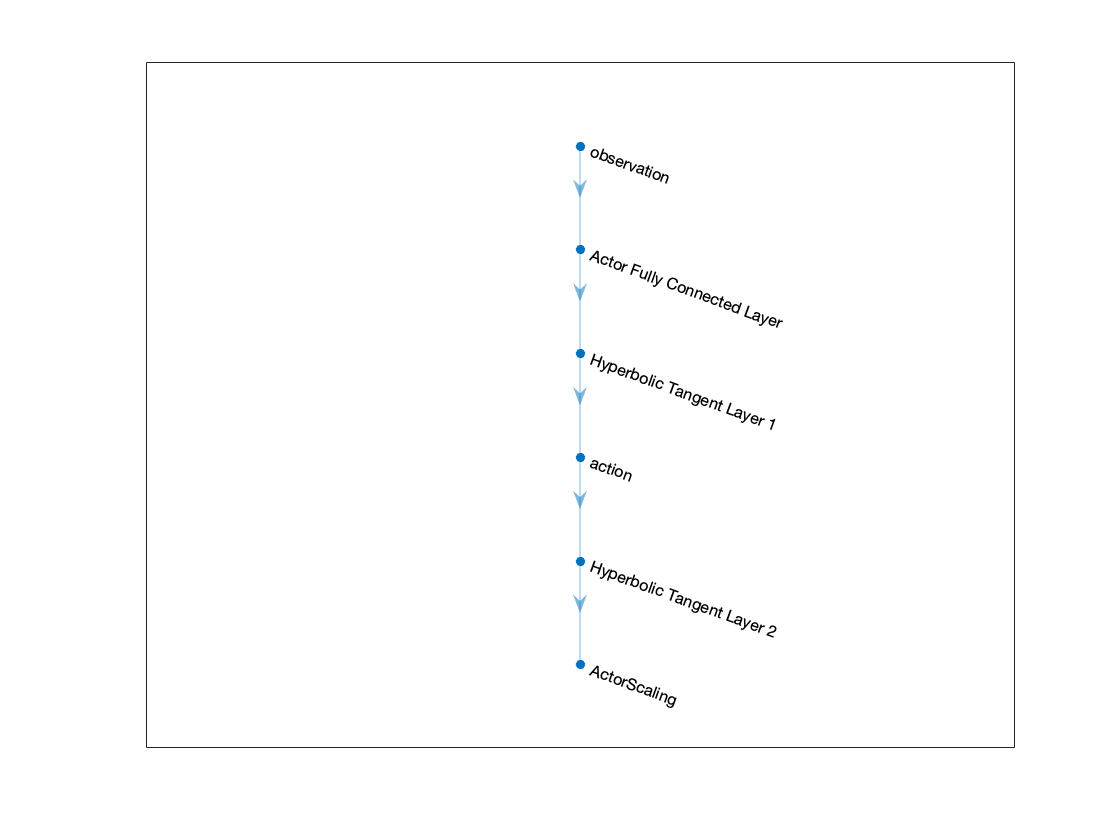

actorNetwork = layerGraph(actorNetwork);
figure
plot(actorNetwork)

To create the DDPG agent, first specify the DDPG agent options using [`rlDDPGAgentOptions`](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c).

agentOptions = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'ExperienceBufferLength',1e6,...
    'DiscountFactor',0.99,...
    'MiniBatchSize',32);

agentOptions.NoiseOptions.StandardDeviation = 0.1*cs.MaxInput;
agentOptions.NoiseOptions.StandardDeviationDecayRate = 1e-4

agentOptions =   rlDDPGAgentOptions with properties:

                           NoiseOptions: [1×1 rl.option.OrnsteinUhlenbeckActionNoise]
                     TargetSmoothFactor: 1.0000e-03
                  TargetUpdateFrequency: 1
    ResetExperienceBufferBeforeTraining: 1
          SaveExperienceBufferWithAgent: 0
                         SequenceLength: 1
                          MiniBatchSize: 32
                    NumStepsToLookAhead: 1
                 ExperienceBufferLength: 1000000
                             SampleTime: 0.0300
                         DiscountFactor: 0.9900


For actor: Use 1-2 hidden layer, with at most 10 neurons in the firsst one and the second one less than one

For critic: 2 dozen neurons

Then, create the agent using the specified actor representation, critic representation and agent options. For more information, see [`rlDDPGAgent`](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef).

agent = rlDDPGAgent(actor,critic,agentOptions);

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run each training episode for at most 10`00` episodes, with each episode lasting at most 500 time steps.

- Display the training progress in the Episode Manager dialog box.

- Stop training when the agent receives an episode reward greater than 260. 

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxepisodes = 1500;
maxsteps = ceil(Tf/Ts);
trainingOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes,...
    'MaxStepsPerEpisode',maxsteps,...
    'Verbose',false,...
    'Plots','training-progress',...
    'ScoreAveragingWindowLength', 50,...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',80);

## Train Round 1: No Noise

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. The observation vector has no noise but goes through the same filtering process.

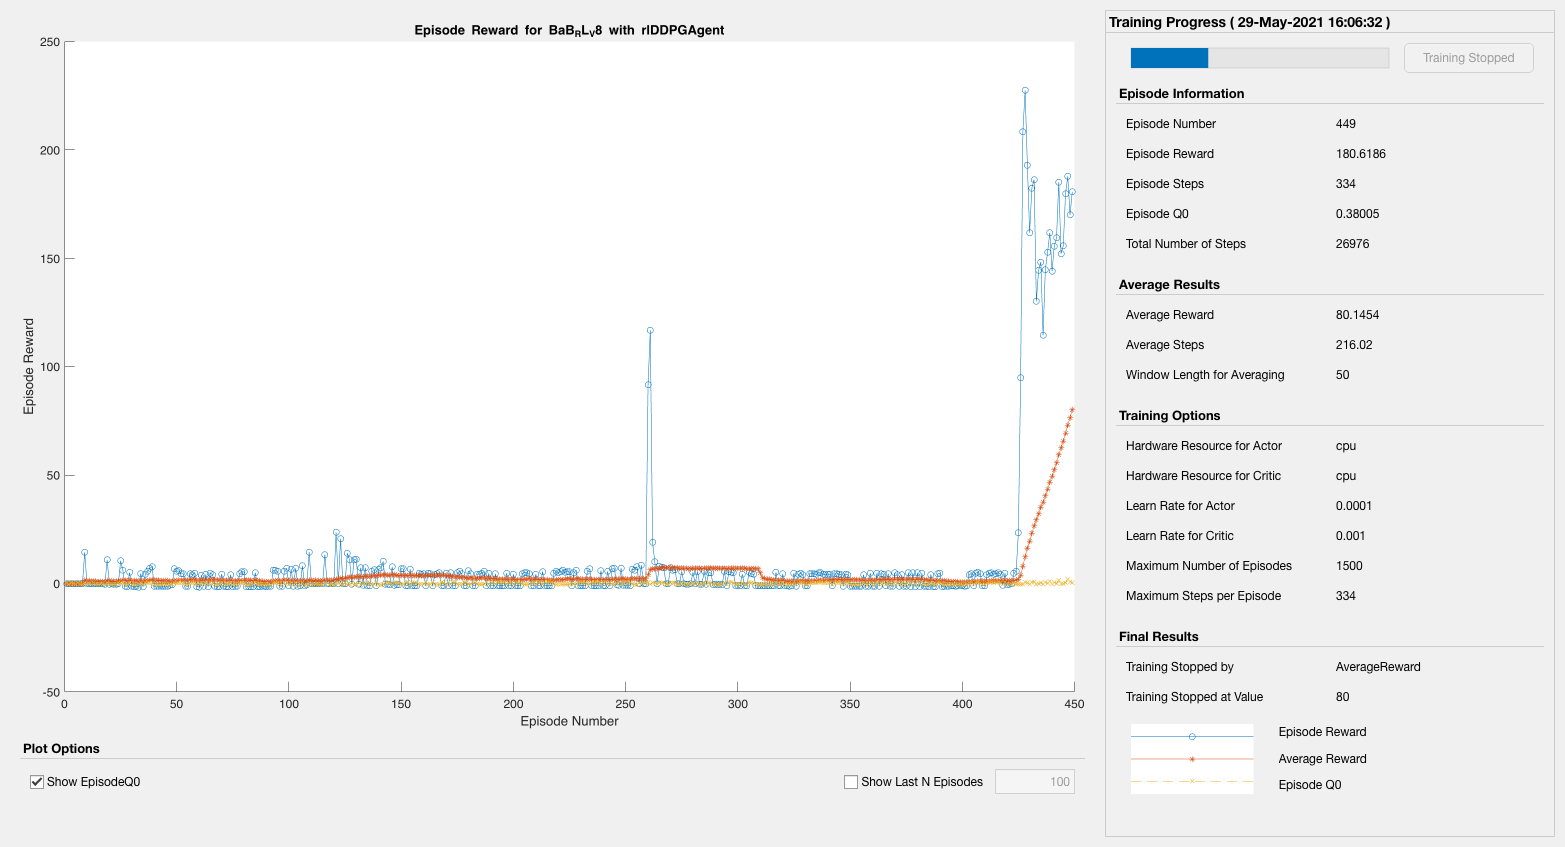

trainingStats = train(agent,env,trainingOpts);

## Train Round 2: Add Noise

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function, except this time, I'm adding noise to the observation vector.

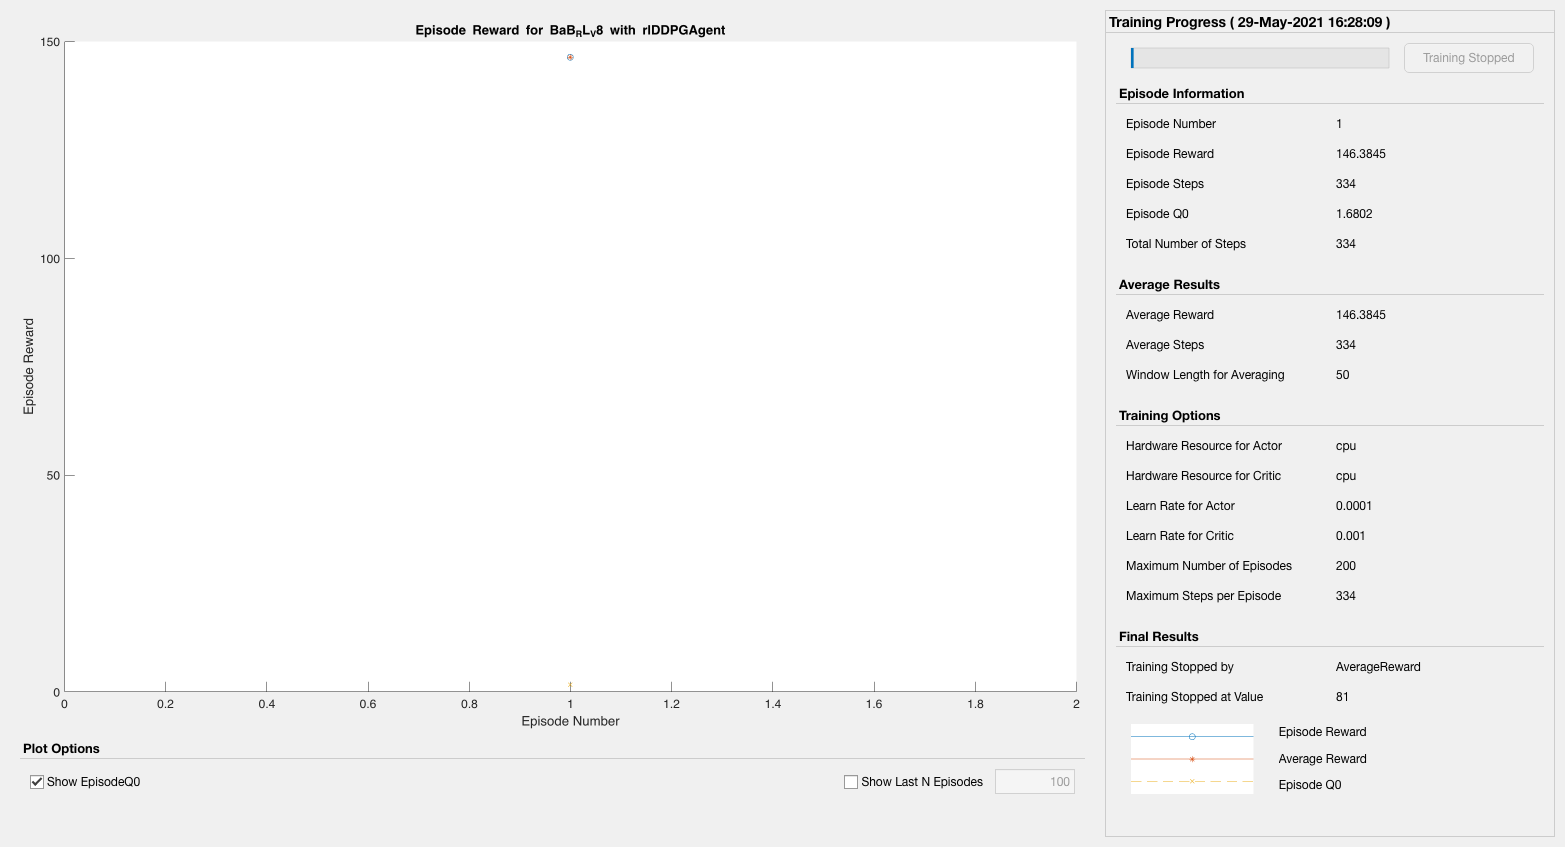

sensor.NoisePower = sensor.var_pos_all_cm*sensor.SampleTime;
trainingOpts = rlTrainingOptions(...
    'MaxEpisodes',200,...
    'MaxStepsPerEpisode',maxsteps,...
    'Verbose',false,...
    'Plots','training-progress',...
    'ScoreAveragingWindowLength', 50,...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',81);
env = rlSimulinkEnv(mdl,[mdl '/RL Agent'],observationInfo,actionInfo);
trainingStats = train(agent,env,trainingOpts);

## Simulate DDPG Agent

To validate the performance of the trained agent, simulate the agent within the Simulink environment by uncommenting the following commands. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

simOptions = rlSimulationOptions('MaxSteps',maxsteps);
experience = sim(env,agent,simOptions);

To demonstrate the trained agent using deterministic initial conditions, simulate the model in Simulink. 

IC = 0.2;
sim(mdl)

ans =   Simulink.SimulationOutput:

                   tout: [397x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


generatePolicyFunction(agent)
testpos = (-.28:.02:.28);
testvel = (-1:0.05:1);
clear RLaction
RLaction(1:length(testpos), 1:length(testvel)) = 0;
for ii = 1:length(testpos)
    for jj = 1:length(testvel)
        observation(1:2, 1, 1) = [testpos(ii) testvel(jj)];
        RLaction(ii,jj) = evaluatePolicy(observation(1:2, 1, 1));
        PDcontroller(ii,jj) = (30*21/10000)*testpos(ii)+(30*21/10000)*testvel(jj);
    end
end

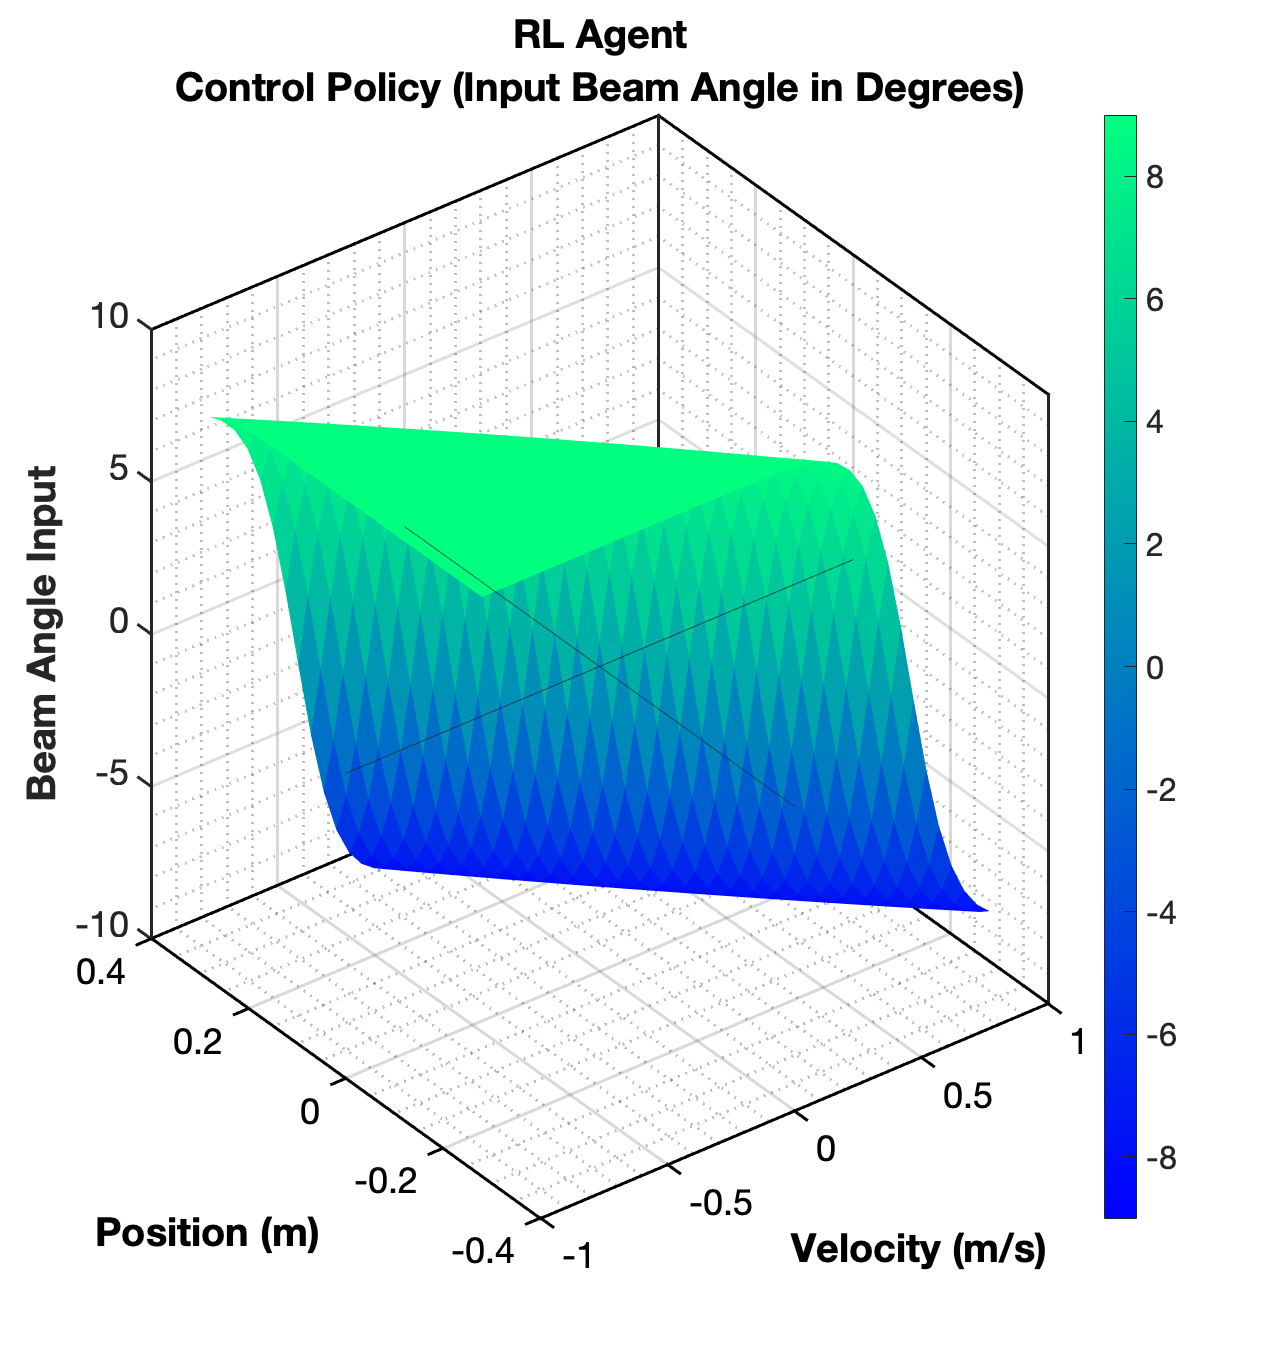

h = figure();
surf(testvel, testpos, RLaction*180, 'EdgeColor', 'none')
% contour(testvel, testpos, RLaction*180, 'LineWidth', 2)
xlabel('Velocity (m/s)');
ylabel('Position (m)');
zlabel('Beam Angle Input');
title('RL Agent', 'Control Policy (Input Beam Angle in Degrees)')
colormap(winter);
colorbar;
xline(0);
yline(0);
% plotter(gcf,1)
plotter(gcf,1)

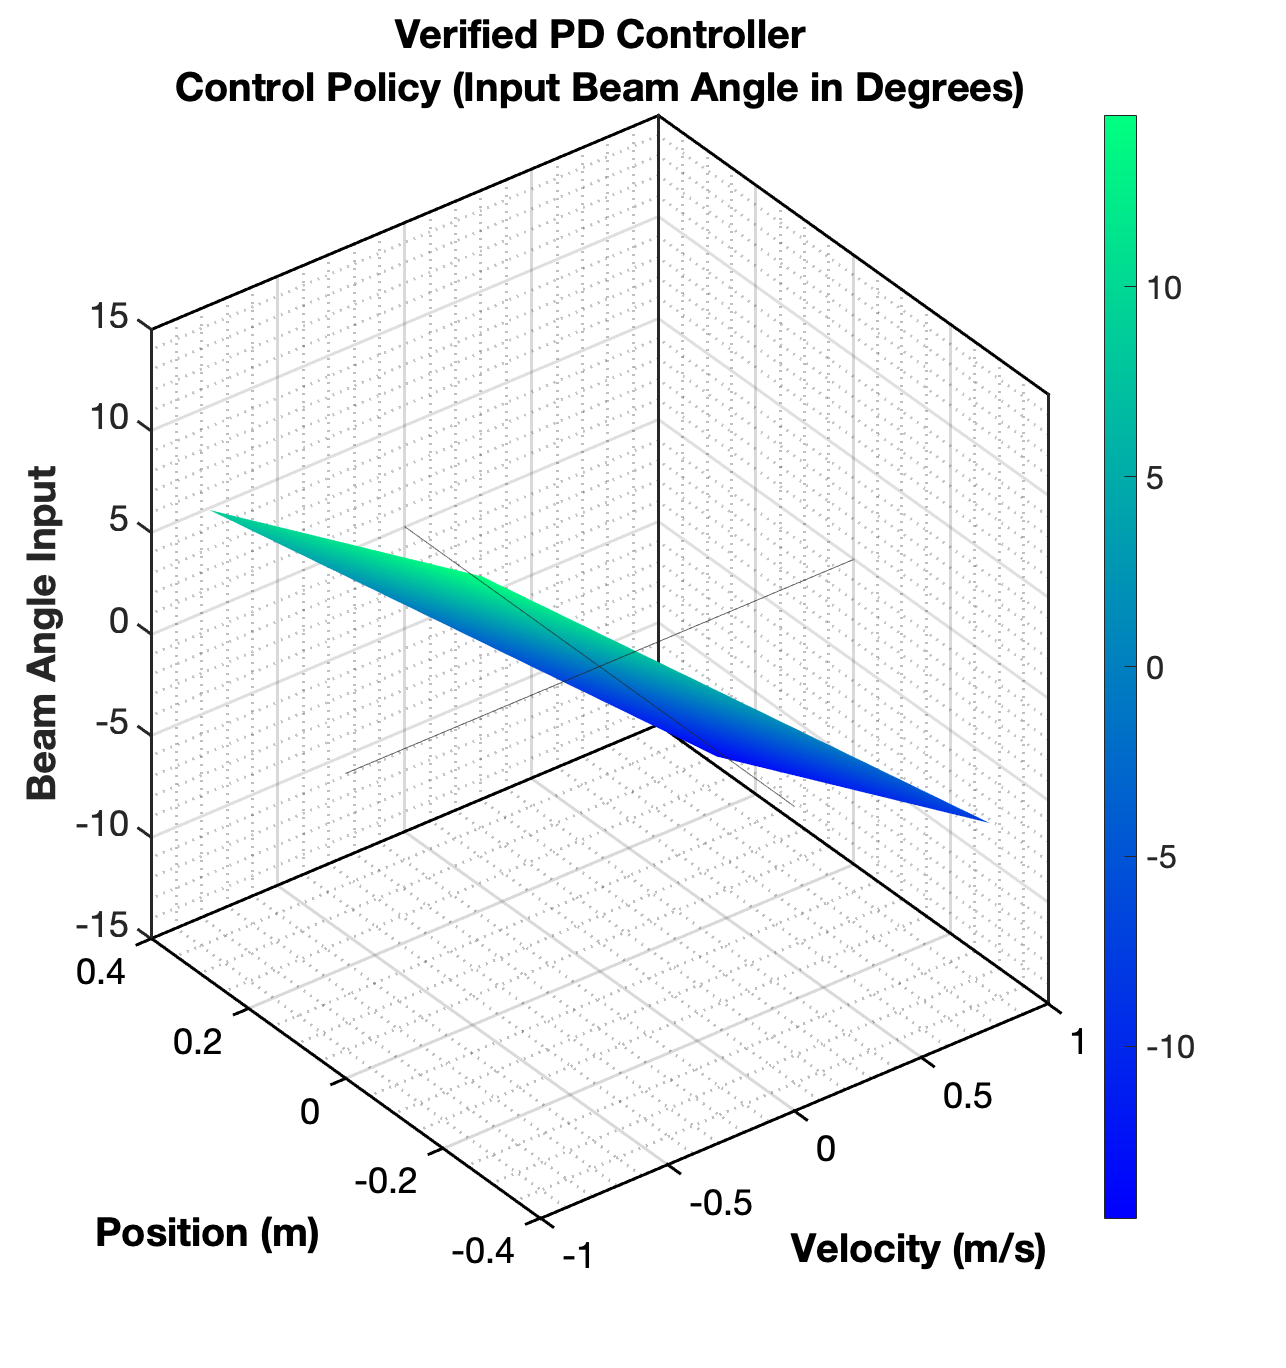


h = figure();
surf(testvel, testpos, -PDcontroller*180, 'EdgeColor', 'none')
% contour(testvel, testpos, -PDcontroller*180, 'LineWidth', 2)
xlabel('Velocity (m/s)');
ylabel('Position (m)');
zlabel('Beam Angle Input');
title('Verified PD Controller', 'Control Policy (Input Beam Angle in Degrees)')
colormap(winter);
colorbar;
xline(0);
yline(0);
% plotter(gcf,1)
plotter(gcf,1)

IC = 0.25;
sim(mdl)

ans =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [397x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 
